## 无穷级数

含变量的级数和

### 泰勒展开--麦克劳林展开

#### taylor(f,'ExpansionPoint',0,'Order',1)

例1.计算cos(x)在0处的六阶泰勒展开

例2.计算atan(x)在0处的5阶展开并画出原函数和展开函数图

%例1
syms x;
ser1=taylor(cos(x),'ExpansionPoint',0,'Order',7)

$$ser1 = -\frac{x^{6}}{720}+\frac{x^{4}}{24}-\frac{x^{2}}{2}+1$$


%例2
ser2=taylor(atan(x),'ExpansionPoint',0,'Order',6)

$$ser2 = \frac{x^{5}}{5}-\frac{x^{3}}{3}+x$$

x=-1.5:0.01:1.5

x =    -1.5000   -1.4900   -1.4800   -1.4700   -1.4600   -1.4500   -1.4400   -1.4300   -1.4200   -1.4100   -1.4000   -1.3900   -1.3800   -1.3700   -1.3600   -1.3500   -1.3400   -1.3300   -1.3200   -1.3100   -1.3000   -1.2900   -1.2800   -1.2700   -1.2600   -1.2500   -1.2400   -1.2300   -1.2200   -1.2100   -1.2000   -1.1900   -1.1800   -1.1700   -1.1600   -1.1500   -1.1400   -1.1300   -1.1200   -1.1100   -1.1000   -1.0900   -1.0800   -1.0700   -1.0600   -1.0500   -1.0400   -1.0300   -1.0200   -1.0100


y1=atan(x)

y1 =    -0.9828   -0.9797   -0.9766   -0.9734   -0.9703   -0.9670   -0.9638   -0.9605   -0.9572   -0.9539   -0.9505   -0.9472   -0.9437   -0.9403   -0.9368   -0.9332   -0.9297   -0.9261   -0.9225   -0.9188   -0.9151   -0.9114   -0.9076   -0.9038   -0.8999   -0.8961   -0.8921   -0.8882   -0.8842   -0.8801   -0.8761   -0.8719   -0.8678   -0.8636   -0.8593   -0.8551   -0.8507   -0.8464   -0.8419   -0.8375   -0.8330   -0.8284   -0.8238   -0.8192   -0.8145   -0.8098   -0.8050   -0.8002   -0.7953   -0.7904


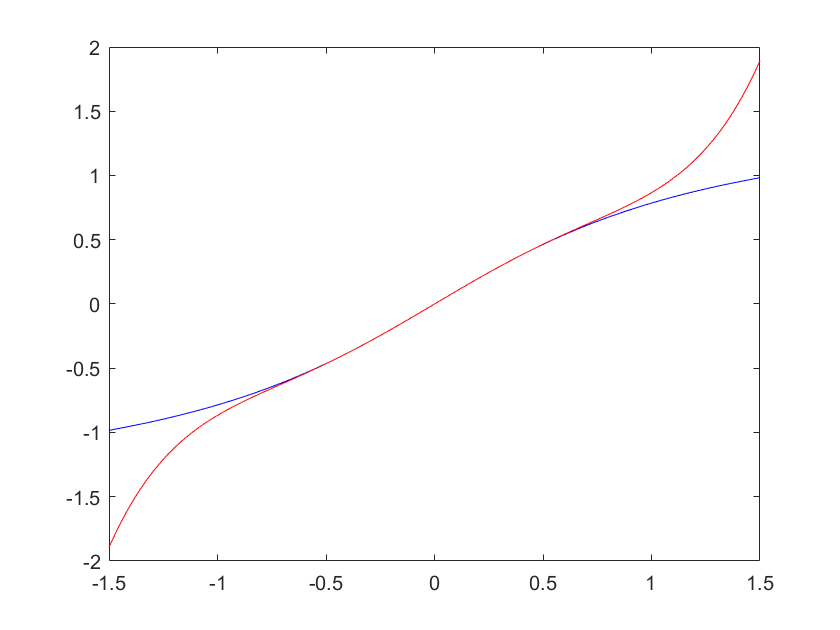

y2=x.^5/5-x.^3/3+x;
plot(x,y1,'b',x,y2,'r-')

### 傅里叶级数

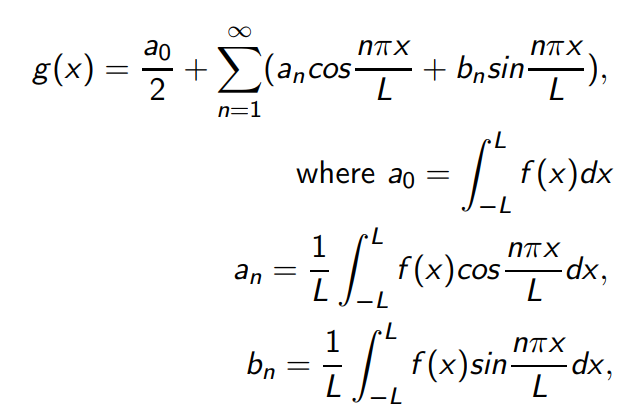

例1.

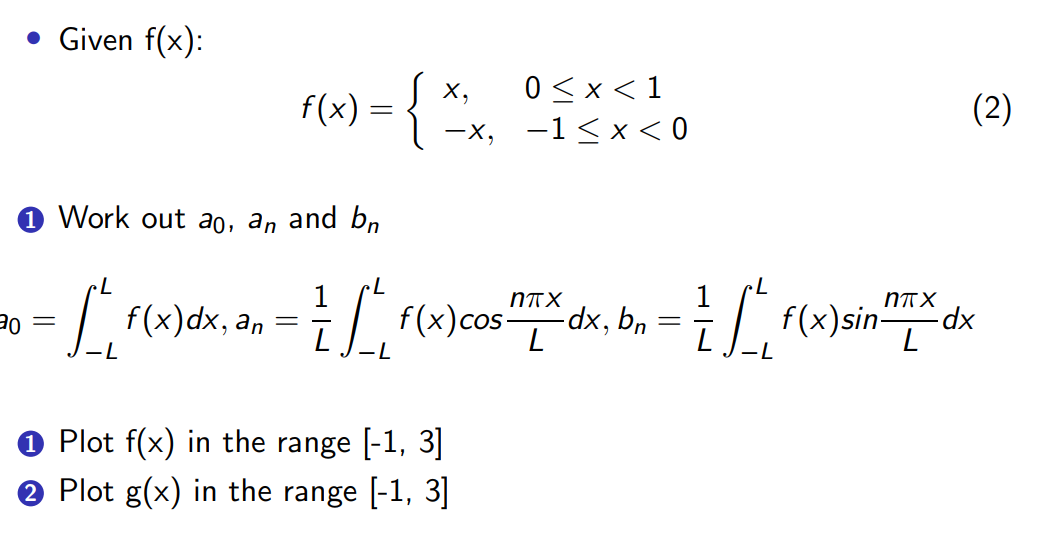

clf
syms x;
N=4

N = 4

a0=int(-x,x,-1,0)+int(x,x,0,1)

$$a0 = 1$$

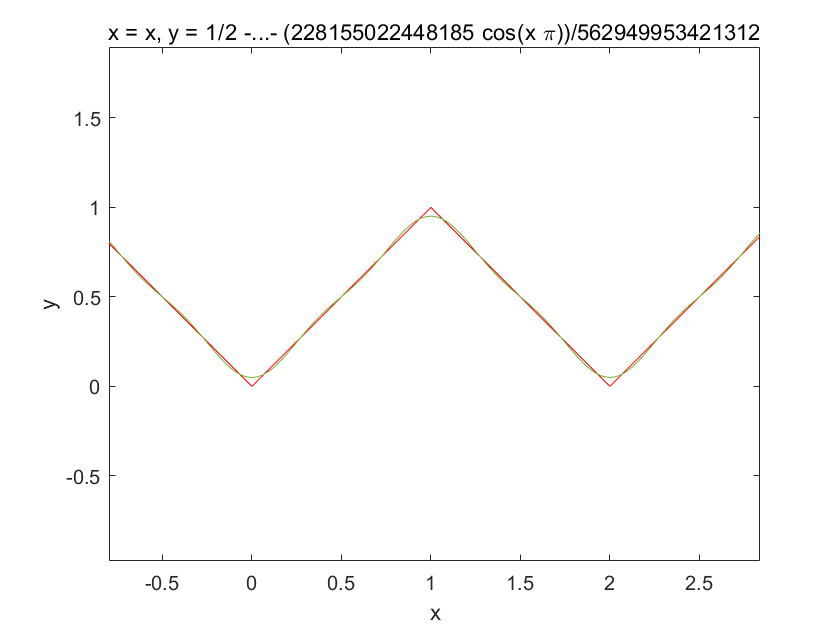

ak=1:1:N;bk=1:1:N;
ga=0;gb=0;
for k=1:N
clf;
ak(k)=int(-x*cos(k*pi*x),x,-1,0)+int(x*cos(k*pi*x),x,0,1);
bk(k)=int(-x*sin(k*pi*x),x,-1,0)+int(x*sin(k*pi*x),x,0,1);
ga=ga+cos(k*pi*x)*ak(k);
gb=gb+sin(k*pi*x)*bk(k);
g=a0/2+ga+gb;

end
x1=0:0.1:1;
y1=x1;
x2=-1:0.1:0;
y2=-x2;
x3=1:0.1:2;
y3=-(x3-2);
x4=2:0.1:3;
y4=x4-2;
plot(x1,y1,'r',x2,y2,'r',x3,y3,'r',x4,y4,'r');
hold on
ezplot(g,[-1,3])

## 微分方程

### dsolve()

#### 单个方程

例1.

例2.

例3.

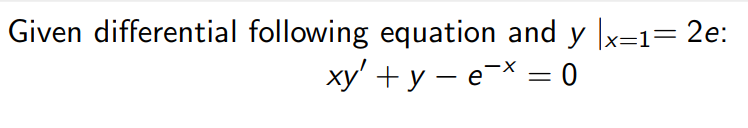

例4.

**simplify(f)化简函数**

y1=dsolve('D2y+D1y=2*y','x')

$$y1 = C_{2}\,{\mathrm{e}}^{x}+C_{1}\,{\mathrm{e}}^{-2\,x}$$

y2=dsolve('D1y+2*x*y=x*exp(-x^2)','x')

$$y2 = C_{1}\,{\mathrm{e}}^{-x^{2}}+\frac{x^{2}\,{\mathrm{e}}^{-x^{2}}}{2}$$

y3=dsolve('x*D1y+y-exp(-x)','y(1)=2*exp(1)','x')

$$y3 = \frac{{\mathrm{e}}^{-1}-{\mathrm{e}}^{-x}+2\,\mathrm{e}}{x}$$

y4=dsolve('D2y-2*D1y+5*y=x*exp(x)*cos(2*x)','x')

$$y4 = C_{1}\,\cos\left(2\,x\right)\,{\mathrm{e}}^{x}-\cos\left(2\,x\right)\,{\mathrm{e}}^{x}\,\left(\frac{\sin\left(4\,x\right)}{64}-\frac{x\,\cos\left(4\,x\right)}{16}\right)-C_{2}\,\sin\left(2\,x\right)\,{\mathrm{e}}^{x}+\sin\left(2\,x\right)\,{\mathrm{e}}^{x}\,\left(\frac{\cos\left(4\,x\right)}{64}+\frac{x\,\sin\left(4\,x\right)}{16}+\frac{x^{2}}{8}-\frac{1}{64}\right)$$

y4=simplify(y4)

$$y4 = \frac{{\mathrm{e}}^{x}\,\left(2\,x\,\cos\left(2\,x\right)-\sin\left(2\,x\right)+4\,x^{2}\,\sin\left(2\,x\right)+32\,C_{1}\,\cos\left(2\,x\right)-32\,C_{2}\,\sin\left(2\,x\right)\right)}{32}$$

#### 方程组

例1.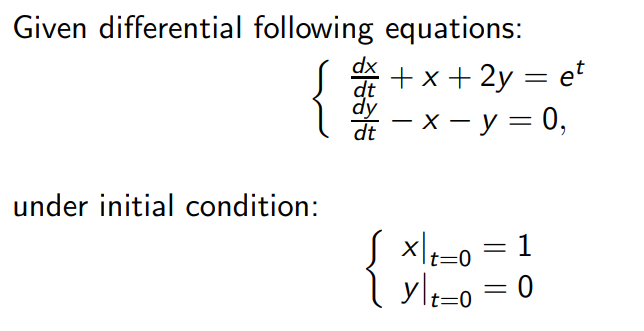

clear;
[x,y]=dsolve('D1x+x+2*y=exp(t)','D1y-x-y=0','x(0)=1','y(0)=0')

$$x = \left(\cos\left(t\right)-\sin\left(t\right)\right)\,\left(\frac{{\mathrm{e}}^{t}\,\left(\cos\left(t\right)+\sin\left(t\right)\right)}{2}+\frac{1}{2}\right)-\left(\frac{{\mathrm{e}}^{t}\,\left(\cos\left(t\right)-\sin\left(t\right)\right)}{2}-\frac{1}{2}\right)\,\left(\cos\left(t\right)+\sin\left(t\right)\right)$$

$$y = \cos\left(t\right)\,\left(\frac{{\mathrm{e}}^{t}\,\left(\cos\left(t\right)-\sin\left(t\right)\right)}{2}-\frac{1}{2}\right)+\sin\left(t\right)\,\left(\frac{{\mathrm{e}}^{t}\,\left(\cos\left(t\right)+\sin\left(t\right)\right)}{2}+\frac{1}{2}\right)$$

x=simplify(x)

$$x = \cos\left(t\right)$$

y=simplify(y)

$$y = \frac{{\mathrm{e}}^{t}}{2}-\frac{\sqrt{2}\,\cos\left(t+\frac{\pi }{4}\right)}{2}$$

### 数值解：欧拉法

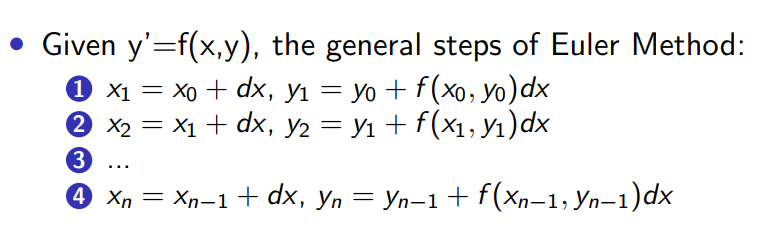

用欧拉法求解微分方程：D1y=1+y+x

%欧拉法
clear;clf;
f1=[];
y=1;
f1=[f1;y];
for x=0.1:0.1:1%步长保持一致
y=y+(1+y+x)*0.1;
f1=[f1;y];%列向量
end

%用dsolve解
f2=dsolve('D1y=1+y+x','y(0)=1','x');

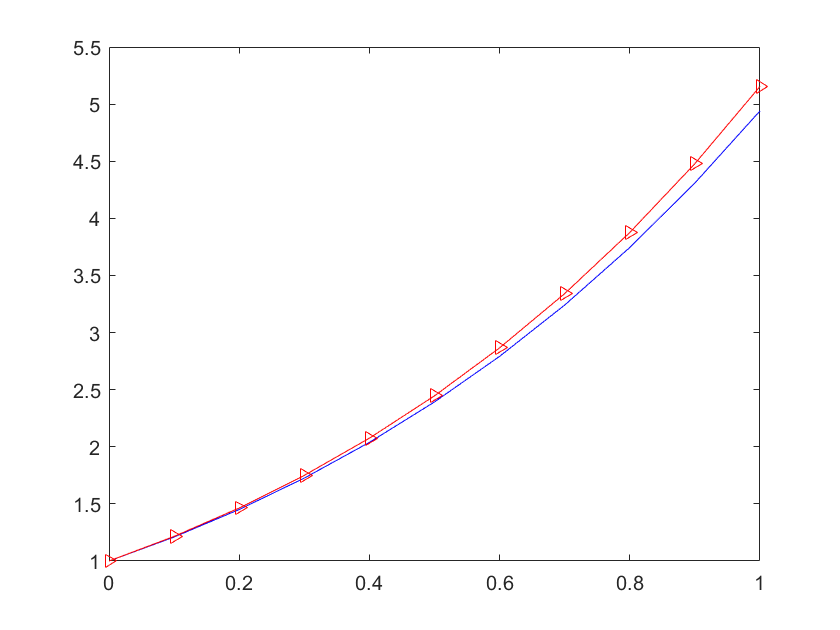

y2=[];
for x1=0:0.1:1
x=x1;
y2=[y2;eval(f2)];
end
x=[0:0.1:1];
plot(x,f1,'b-',x,y2,'r->');

### 数值解：龙格-库塔法

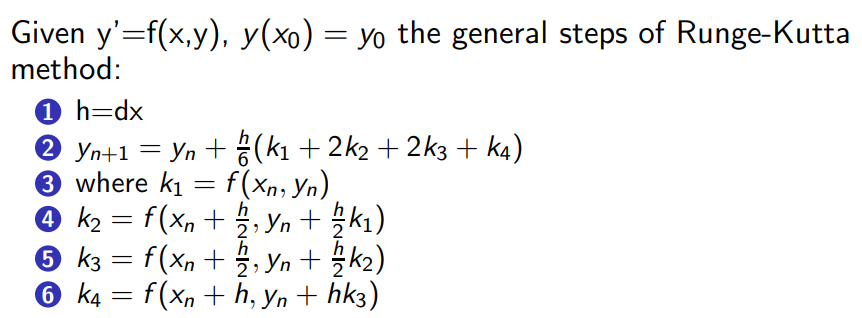

用龙格-库塔法求解微分方程：D1y=1+y

clear;
clf;
x=0:0.1:1;
h=0.1;
y=1;
f1=[];
f1=[f1;y];
for i=1:1:(length(x)-1)
k1=1+y;
k2=1+y+h/2*k1;
k3=1+y+h/2*k2;
k4=1+y+h*k3;
y=y+h/6*(k1+2*k2+2*k3+k4);
f1=[f1;y];
end
f2=dsolve('D1y=1+y','y(0)=1','x');

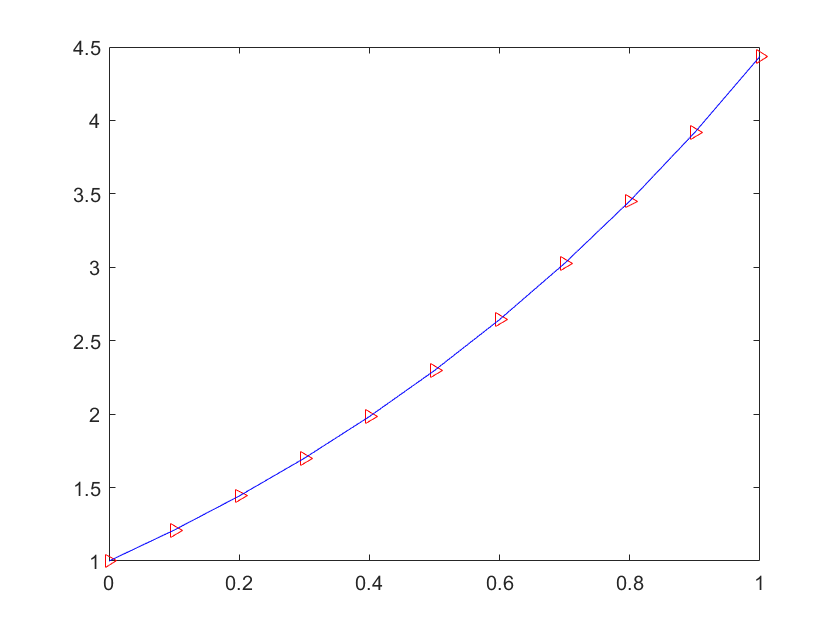

y2=[];
for x=0:0.1:1
y2=[y2;eval(f2)];
end
x=[0:0.1:1];
plot(x,f1,'r->',x,y2,'b-');